clear;clc;close all
layerfolder='../data/layers/';%route to folder with ambiental data
Dimensions = ReadLayers(layerfolder);

----Reading layers----
Elapsed time is 10.032639 seconds.


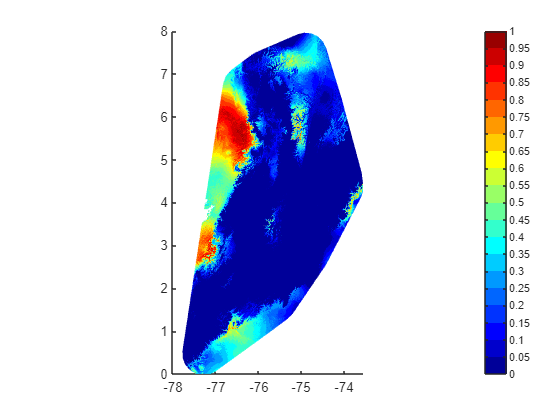

InfoInitialPoint = InitialPoint(Dimensions);
MapInfo = NicheGeneration(Dimensions, InfoInitialPoint, 0.5, true);

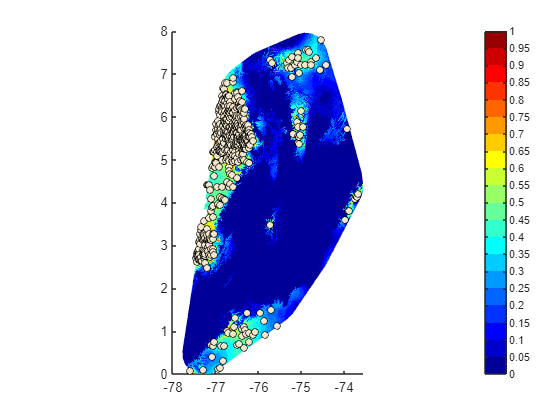

T = samplingVS(Dimensions, InfoInitialPoint, MapInfo, 500, -3, true, 'GenSP', true, true);

----Finding clusters----


1 clusters identified


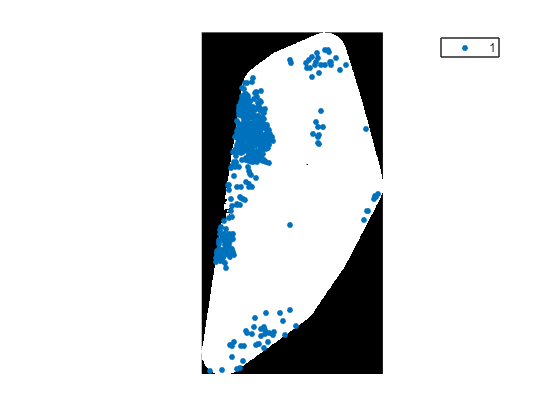

Elapsed time is 7.934622 seconds.
----Finding correlation----
Elapsed time is 10.736758 seconds.
----Creating predictors----
¡All done!
Elapsed time is 10.874757 seconds.


close all
[data,outland] = bnm_prep(T, Dimensions, false, 0.7, true, false);

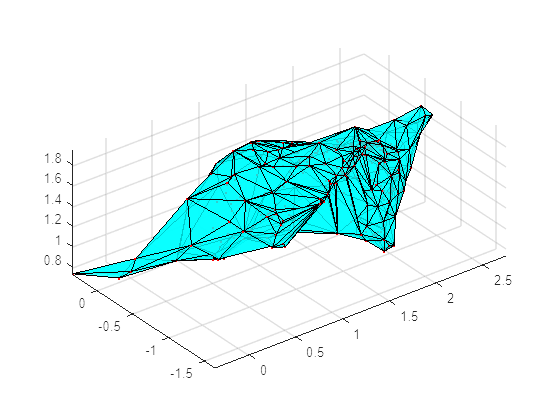

radius =     1.5128    0.9648    1.7203    1.6571    1.7813    1.6374    1.7033    1.7269    1.1742    1.6723    1.4749    1.7039    1.7663    1.5681    1.5086    1.3103    1.4972    1.2681    0.9555    0.5537    1.4652    1.0010    1.7688    2.0867    1.2587    1.4387    1.5303    1.6347    0.9800    1.4326    1.5849    1.2609    1.2909    1.0740    1.6701    1.4600    1.5168    0.4175    1.8581    0.8270    1.1055    0.8089    1.2179    0.9187    0.4332    1.1761    1.1226    0.4596    1.5267    1.5207
    0.2244    1.0528    0.1030    0.1629    0.1709    0.1169    0.0989    0.2641    0.6878    0.1411    0.2641    0.3136    0.2693    0.6189    0.2681    0.5135    0.3119    0.5164    1.2629    1.7443    0.5906    1.0645    1.0015    0.5258    0.6287    0.5916    0.4491    0.2646    0.9868    0.6014    0.2556    0.5255    0.4919    0.7735    0.8658    0.3503    0.3676    1.8555    1.0429    1.2371    0.8807    1.6999    0.8160    1.1351    1.7343    0.6855    0.9421    1.7018    0.6088

radiusClass =     0.2244    0.3467    0.0672    0.1356    0.1352    0.1135    0.0929    0.1443    0.2614    0.1011    0.2125    0.0625    0.1489    0.1576    0.1605    0.2476    0.1048    0.2802    0.2832    0.4675    0.1416    0.2670    0.2315    0.1068    0.2190    0.1197    0.1840    0.0932    0.2449    0.1589    0.1760    0.2301    0.2883    0.2937    0.1052    0.2632    0.1643    0.4175    0.2504    0.3512    0.1624    0.3668    0.2886    0.3395    0.4332    0.2934    0.3552    0.4596    0.0755    0.0807


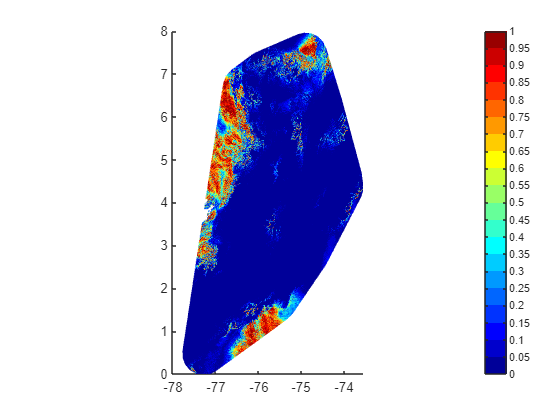

close all, clf
show=true;%show graphics
outlier=false;%remove outliers before PCA with method in https://github.com/AntonSemechko/Multivariate-Outliers
outlier2=false;%remove outliers after PCA with method in https://github.com/AntonSemechko/Multivariate-Outliers
class = ColoringBorder(data,show,outlier,outlier2,1);

MapMetric(MapInfo.Map,class.map,false)

ans =     0.9491    0.8241


MapMetric(MapInfo.Map,dataf.Map,false)

ans =     0.9010    0.8779


newInfo = samplingVS(Dimensions, InfoInitialPoint, MapInfo, 100, -3, true, 'GenSP', true, true);
[dataNew,outland] = bnm_prep(newInfo, Dimensions, false, 0.7, false, false);
newPoints(dataNew{1},class)

----Modeling----


ij = 1

-Model 1


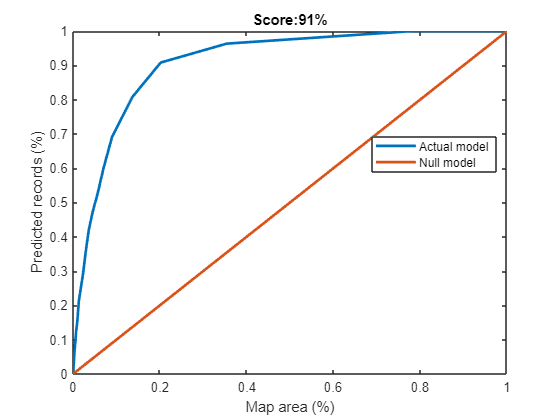

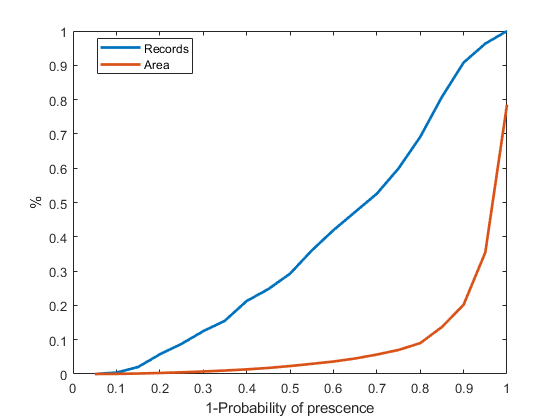

Elapsed time is 1.329663 seconds.


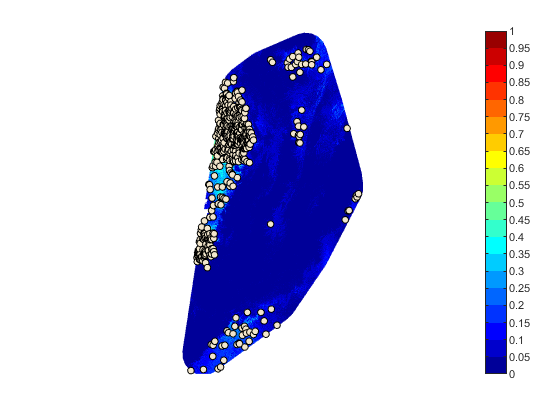

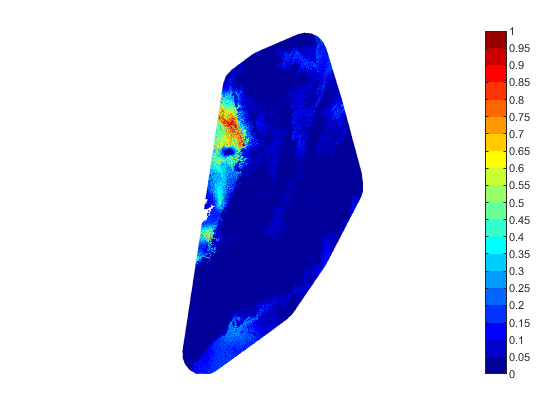

dataf = bnm_modeling(data, '', true, 4, false);

close all
show=true;%show graphics
outlier=false;%remove outliers before PCA with method in https://github.com/AntonSemechko/Multivariate-Outliers
outlier2=true;%remove outliers after PCA with method in https://github.com/AntonSemechko/Multivariate-Outliers
data = bnm_modeling2(data{1},show,outlier,outlier2)